%% test_preproc_and_register.m  (with folder‐picker & multi‐frame fallback)

% 0)  Setup: add your src/ folder to the path
projectRoot = pwd;  
srcFolder   = fullfile(projectRoot,'src');
addpath(genpath(srcFolder));
fprintf('Added to path: %s\n', srcFolder);

Added to path: /Users/otto/Documents/UNI/TUM/Master/2. Semester Master/Computer Vision/challange.nosync/Computer_vision_challenge/src




% 1)  Choose data folder (default or via dialog)
defaultFolder = fullfile(projectRoot,'datasets_moodle/','Frauenkirche');
if isfolder(defaultFolder)
    folderPath = defaultFolder;
else
    folderPath = uigetdir(projectRoot, ...
       'Select folder with your Dubai‐UAE images');
    if folderPath == 0
        error('No folder selected. Aborting.');
    end
end
fprintf('Using folder: %s\n', folderPath);

Using folder: /Users/otto/Documents/UNI/TUM/Master/2. Semester Master/Computer Vision/challange.nosync/Computer_vision_challenge/datasets_moodle/Frauenkirche






% Remove any .DS_Store in the target folder before scanning
dsFile = fullfile(folderPath, '.DS_Store');
if isfile(dsFile)
    delete(dsFile);
    fprintf('Deleted hidden file: %s\n', dsFile);
end 

% 2)  Preprocess all images in the folder
pre = preprocess_images(folderPath);

Error using preprocess_images (line 13)
Input must be a cell array of image file paths.

nImgs = numel(pre);
fprintf('Found %d preprocessed frames.\n', nImgs);
assert(nImgs >= 2, 'Need at least two images to register.');

% 3)  Pick endpoints by index (here: 1 → 4)
idxA = 1;
idxB = 2;
assert(idxB <= nImgs, 'Index idxB (%d) exceeds # frames (%d)', idxB, nImgs);
movingRGB = pre(idxA).image;
fixedRGB  = pre(idxB).image;
fprintf('Registering frame %d (%s) → frame %d (%s)\n', ...
    idxA, pre(idxA).name, idxB, pre(idxB).name);

% 4)  Build the SURF config with the full sequence for fallback
imgs = { pre.image };  % cell array of all frames
cfgSURF = struct( ...
    'MetricThreshold',300, ...
    'MatchThreshold',100, ...
    'TransformType','projective', ...
    'MinInliers',30, ...            % threshold to decide fallback
    'ImageSequence',{ imgs }, ...       % full chronological sequence
    'StartIdx',idxA, ...            % index of movingRGB in that sequence
    'EndIdx',idxB ...               % index of fixedRGB in that sequence
);

% 5)  Register (direct or chained)
reg = registerImagesSURF(movingRGB, fixedRGB, cfgSURF);
% 6)  Visualise only A→B la
figure;
imshowpair(reg.registered, fixedRGB, 'blend');
title(sprintf('Frame %d → Frame %d (blended)', idxA, idxB));

fprintf('Done.  Putative matches: %d; Inliers: %d.\n', ...
    numel(reg.matches.fixed), nnz(reg.inlierIdx));


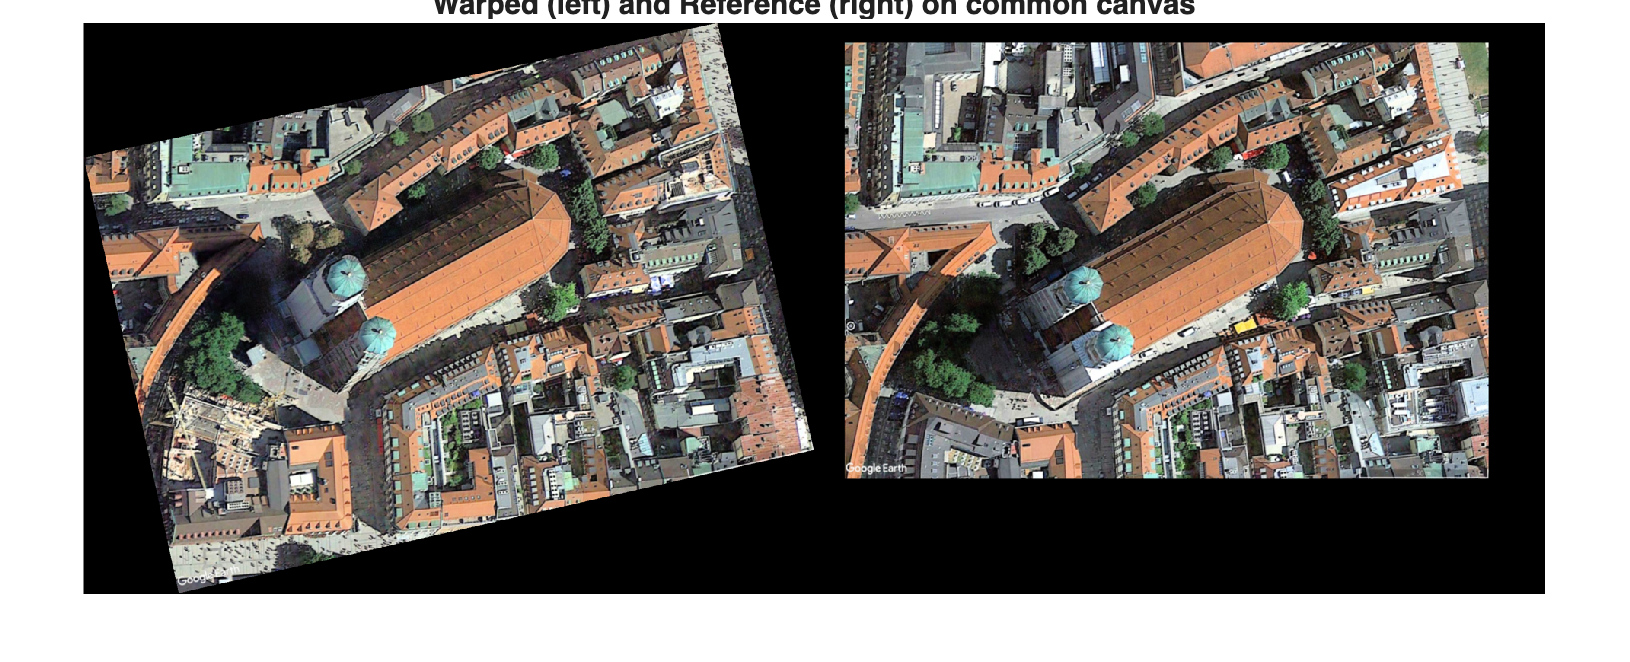

%% 6) Show both images in a common, uncropped canvas -------------

% A) Warp moving onto its own automatically‐sized frame
[movingWarped, Rmoving] = imwarp(movingRGB, reg.tform);
 

% B) Reference's original frame
Rfixed = imref2d(size(fixedRGB));

% C) Compute union of world‐limits
xAll = [Rmoving.XWorldLimits  Rfixed.XWorldLimits];
yAll = [Rmoving.YWorldLimits  Rfixed.YWorldLimits];

Rout = imref2d( ...
    ceil([ diff([min(yAll) max(yAll)])  diff([min(xAll) max(xAll)]) ]), ...
    [min(xAll) max(xAll)], ...
    [min(yAll) max(yAll)] );

% D) Resample both into that big canvas
movingFull = imwarp(movingRGB, reg.tform,        'OutputView', Rout);
fixedFull  = imwarp(fixedRGB,  affine2d(eye(3)), 'OutputView', Rout);

% E) Montage side‐by‐side
figure('Name','Full‐extent aligned comparison');
montage({movingFull, fixedFull}, 'Size', [1 2]);
title('Warped (left) and Reference (right) on common canvas');

%% 7) Additional visualisations (with guards) -----------------------

% A) Matched‐feature montage (only if we have matches)
if ~isempty(reg.matches.fixed) && ~isempty(reg.matches.moving)
    figure;
    showMatchedFeatures(...
        fixedRGB, movingRGB, ...
        reg.matches.fixed, reg.matches.moving, ...
        'montage', 'PlotOptions', {'go','ro','y--'});
    title('SURF feature correspondences');
else
    warning('No SURF inliers found → skipping matched‐features plot.');
end

% B) Absolute‐difference map
diffMap = imabsdiff(reg.registered, fixedRGB);
figure;
imshow(diffMap)
title('Absolute RGB difference');
colorbar

% C) Heat‐map overlay of change
lumDiff = im2gray(diffMap);
figure; imshow(fixedRGB); hold on
h = imshow(lumDiff);
colormap(gca,'hot'); colorbar
set(h,'AlphaData',mat2gray(lumDiff)) 
title('Heat‐map of change overlaid on reference')

